% connect to the Neato
neatov2.connect('192.168.17.207');

Connecting to the Neato.
Testing connection.
Connection successful.


neatov2.testConnection();

The connection appears to be working.



angles = [0; 45; 90; 135];
pos = [0, 0; 0, 0; 0, 1; 1, 1.5];
scans = cell(4,1);

for i = 1:size(pos,1)
    disp(['Move the Neato to position x=', ...
           num2str(pos(i,1)), ...
           ' y=', ...
           num2str(pos(i,2)), ...
           ' at an angle of ', ...
           num2str(angles(i)), ...
           ' degrees counterclockwise from the x-axis']);
pause;
    scans{i} = neatov2.receive();
end

Move the Neato to position x=0 y=0 at an angle of 0 degrees counterclockwise from the x-axis
Move the Neato to position x=0 y=0 at an angle of 45 degrees counterclockwise from the x-axis
Move the Neato to position x=0 y=1 at an angle of 90 degrees counterclockwise from the x-axis
Move the Neato to position x=1 y=1.5 at an angle of 135 degrees counterclockwise from the x-axis


save('HW8_LIDAR_data','angles','pos','scans');

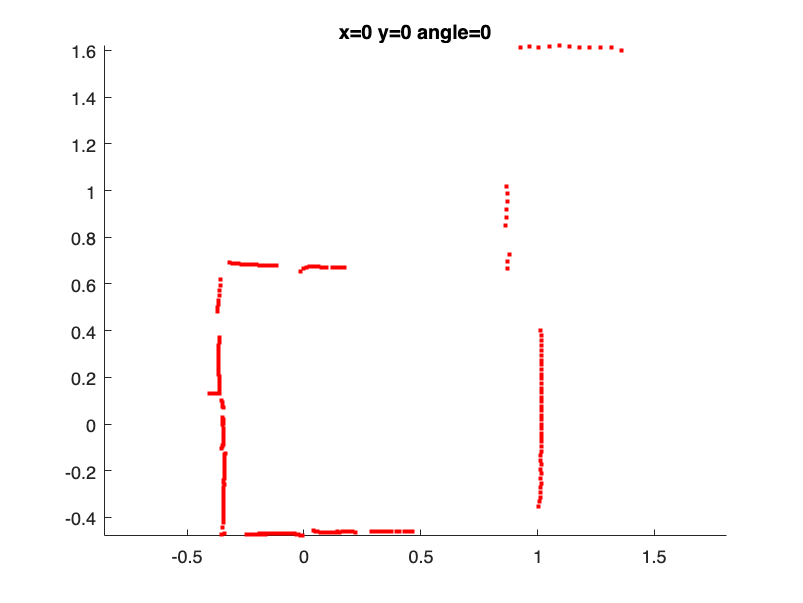

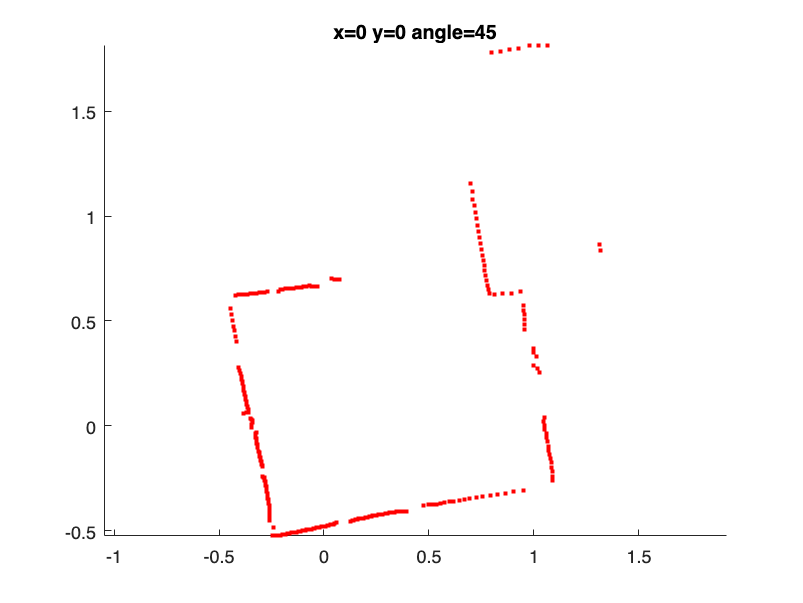

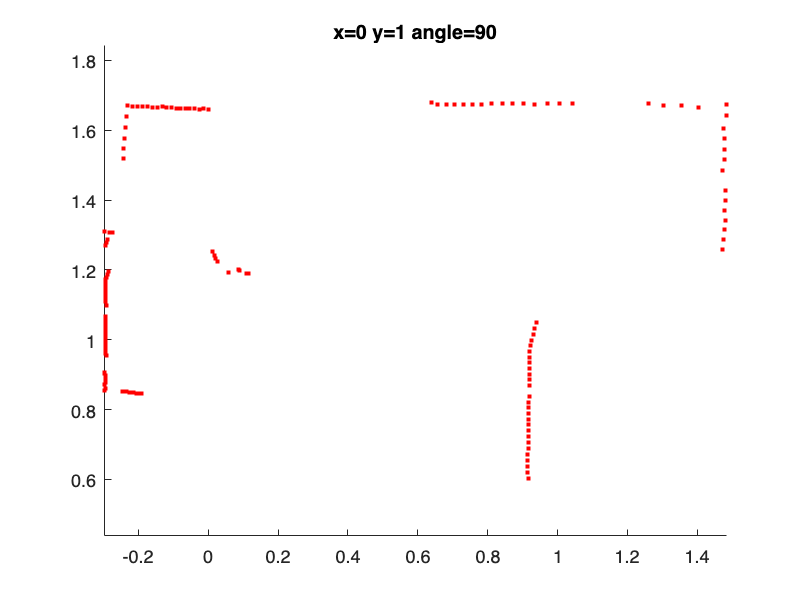

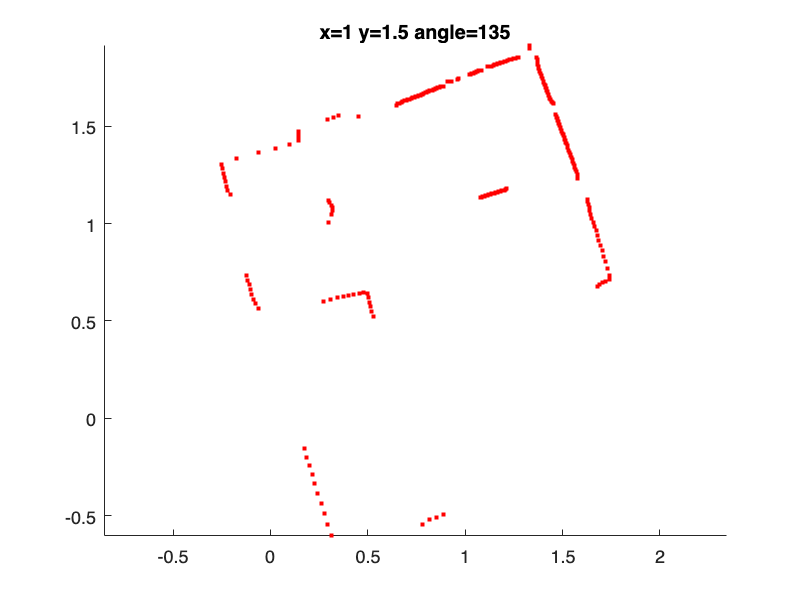

clf;
load('HW8_LIDAR_data.mat', 'angles', 'pos', 'scans');

% Precompute the translation matrix (constant)
T_NS = [1 0 -0.082; 0 1 0; 0 0 1];

% Initialize the superimposed figure
superimposed = figure;
title('Superimposed Plots');
hold on;
axis equal;

for i = 1:size(pos, 1)
    rad = deg2rad(angles(i));
    R_GN = [cos(rad) -sin(rad) pos(i,1);
            sin(rad)  cos(rad) pos(i,2);
            0         0        1];

    global_data = R_GN * T_NS;

    ranges = scans{i}.ranges;
    thetasInRadians = scans{i}.thetasInRadians;
    cos_thetas = cos(thetasInRadians);
    sin_thetas = sin(thetasInRadians);
    cartesian_coordinates = [ranges .* cos_thetas; ranges .* sin_thetas];

    valid_indices = ranges > 0;
    cartHomogeneous = [cartesian_coordinates(:, valid_indices); ones(1, sum(valid_indices))];

    global_final = global_data * cartHomogeneous;

    figure;
    scatter(global_final(1,:), global_final(2,:), 'r.');
    x = num2str(pos(i,1));
    y = num2str(pos(i,2));
    orientation = num2str(angles(i));
    title(['x=', x,' y=', y,' angle=', orientation]);
    axis("equal");

    figure(superimposed);
    scatter(global_final(1,:), global_final(2,:), 'r.');
end

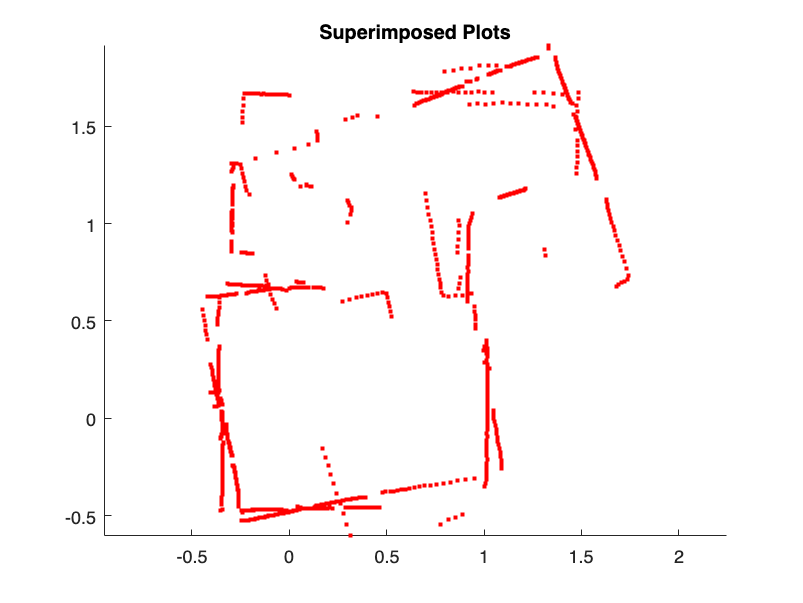


hold off;
axis equal;